# Perform Techno-Economic Analysis of Microgrids

## Techno-Economic Analysis

Techno-economic analysis of microgrids is a comprehensive study that integrates technical performance and economic viability to assess the feasibility and effectiveness of different microgrids. Microgrids comprise multiple distributed energy resources (DERs) including solar panels, wind turbines, generators, combined heat and power (CHP) plants, energy storage systems, and controllable loads. To meet the energy demands while minimizing the overall cost, the techno-economic analysis identifies the optimal configuration and operation of these components.

The analysis starts with the identification of various technical parameters of different components in the microgrid. This identification includes ratings of the energy generation units, the storage capacity and efficiency of battery energy storage system, and the characteristics of the load. Economic parameters play a vital role in this analysis. These parameters can be capital costs, operational and maintenance costs, fuel costs, and potential revenue from energy sales or savings. Incentives and subsidies for renewable energy installations can also play a significant role in the economic evaluation. This analysis considers the time value of money by applying discount rates to future cash flows, enabling the calculation of net present value (NPV), internal rate of return (IRR), and payback period. These financial metrics help in assessing the profitability and economic viability of the microgrid installation over a period of time.

One of the key aspects of the techno-economic analysis is the optimization of microgrid design and operation. You can use optimization techniques to find the best configuration of energy resources and their operational strategies. This technique involves determining the optimal sizes of generation units and storage systems, as well as the optimal scheduling of these resources to meet the load demand that minimizes the overall cost. Constraints such as technical limitations, regulatory requirements, and environmental impacts are taken into account during the optimization.

In addition to optimization, sensitivity analysis is often conducted to understand the impact of various parameters on the overall performance and cost of the microgrid. This analysis helps in identifying the most critical factors that influence the economic viability and in developing strategies that can withstand uncertainties in fuel prices, load growth, and technology costs.

This flowchart describes the steps of a techno-economic analysis

                                                                                     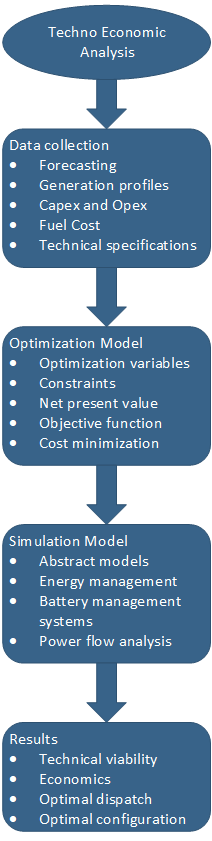

In the first step, you use an optimization algorithm to determine the ratings of different assets in the microgrid and the optimal dispatch of the controllable assets such as the battery and generator. To develop a balanced and feasible solution, the optimization process considers various constraints such as power limits, resource availability, and power balance. Once you identify the optimal configuration, you feed these results into a simulation model. The simulation replicates the microgrid operational behavior over time, accounting for dynamic factors such as fluctuating energy demands, and weather conditions. This step helps in validating the optimization results by providing insights into the system performance under real-world conditions. Finally, in the third step, you analyze the simulation results to assess the techno-economic viability of the proposed microgrid solution. This analysis includes evaluating key performance indicators such as the energy efficiency, cost savings, return on investment, and environmental impact. By comparing these metrics against predefined goals, stakeholders can make informed decisions about the implementation and scaling of the microgrid system. 

## Assets in the Microgrid

You can include different energy resources in the analysis depending on your requirement. This example considers these energy sources:

- Solar PV Plant

- Wind Farm

- Generator Set

- Battery Energy Storage                                          

To determine the solar irradiance, you can provide lattitude and longitude as inputs to the analysis. The  [`solarRadiation`](matlab:open('./+forecast\solarPower.m')) function calculates the solar irradiance for the required amount of time. The analysis assumes that the solar plant always operate with maximum power point tracking (MPPT). The analysis determines the output of the solar plant by multiplying the solar irradiance with the `solarRating` optimization variable

You can load a MAT file with the data for wind speed for the requried amount of time. You can also specify the MPPT for the wind turbine.

## Optimization Problem

The decision variables in this analysis are the ratings of different DERs, renewable sources, and energy storage system. To determine the sizing of different assets and the optmial charging and discharging profile of the energy storage system, this example uses the Optimization Toolbox™.  For more information about the optimization problem setup, see  [Setup Optimization Problem and Architecture](matlab:open('./MicrogridOptimization.mlx'))

## Model for Techno-Economic Analysis

### Model

modelName = "TechnoEconomicMicrogrid";

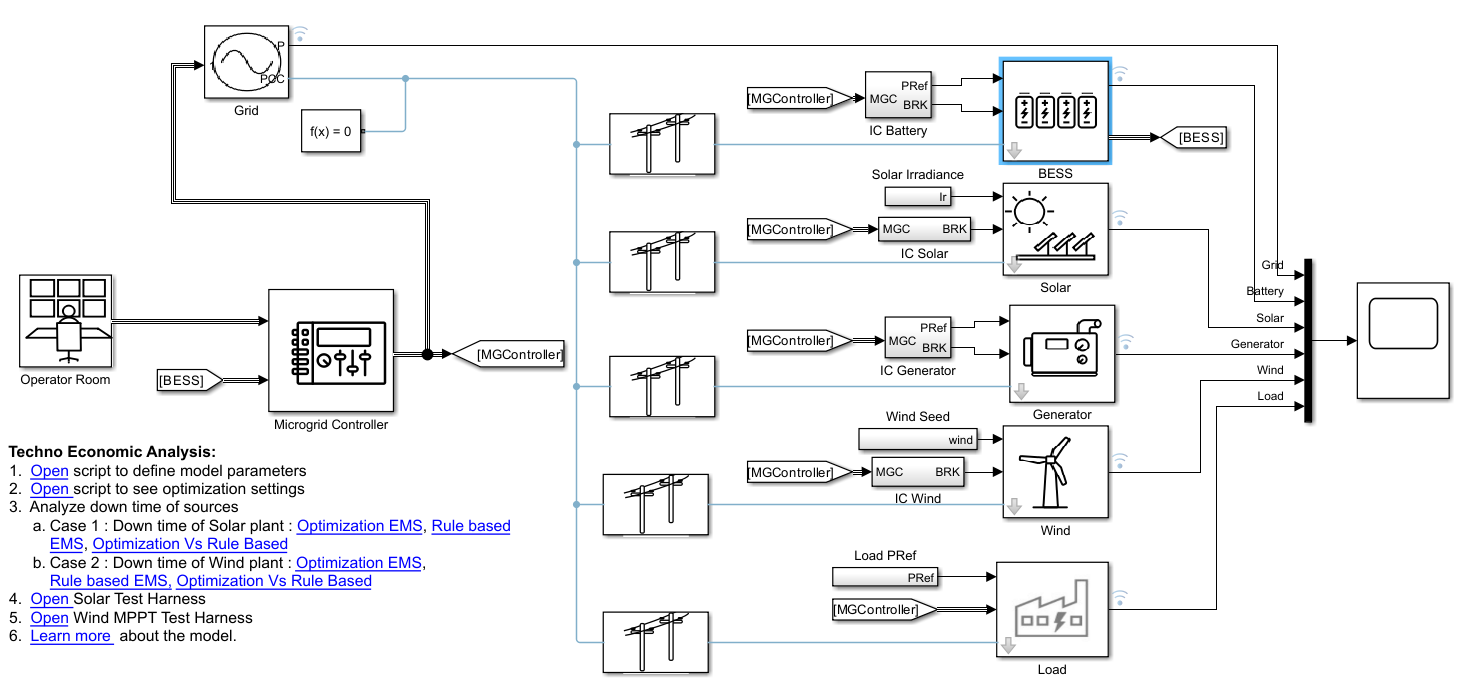

### Explore Components for Techno-Economic Microgrid

This example comprises these main components:

- Battery Energy Storage System (BESS).

- Solar PV Plant

- Wind Farm

- Generator

- Loads

- Microgrid controller

- `OperatorControlRoom` subsystem that gives signals to different circuit breakers.

For more information about these components, see [Components of Techno-Economic Microgrid](matlab:open('..\..\Overview\Techno Economic Analysis\MicrogridComponents.html'))

## Define Parameters and Run Simulations

To verify the different microgrid operations, controller functions, and monitor system behaviors, you simulate different scenarios. In this example, you can simulate two different scenarios:

- Case 1: Solar PV plant maintanence

- Case 2: Wind farm maintanence 

First run the optimization to get the ratings of different assets, and battery charging and discharging profile. You can configure different inputs to the optimization process in [Configure Parameters for Techno Economic Analysis](matlab:open('./MicrogridTechnoEconomic.mlx')). Feed these optimal values to the simulation.

## Run Optimization

MicrogridTechnoEconomic
normalizedPower.solar = normalizedSolarPower;
normalizedPower.wind = normalizedWindPower;
npv.correctionFactor = NPVCorrection;
npv.years = years;
npv.discountRate = discountRate;
load_system('TechnoEconomicMicrogrid');
components = {'Grid','Solar','Wind','Battery','Generator','Load'};
components = setComponents(solution,components);

#### Calculate ratings of Assets

asset = {'Battery'; 'Solar'; 'Wind'; 'Generator'};
rating = [solution.batteryEnergyRating; solution.solarRating; solution.windRating; solution.generatorRating];
unit = {'kWh';'kW';'kW';'kW'};
T = table(asset, rating, unit, 'VariableNames', {'Asset', 'Rating' 'Unit'});

The table shows different assets in the microgrid and the corresponding optimized rating.

disp(T);

        Asset        Rating     Unit  
    _____________    ______    _______

    {'Battery'  }      4057    {'kWh'}
    {'Solar'    }    1137.7    {'kW' }
    {'Wind'     }    586.94    {'kW' }
    {'Generator'}       100    {'kW' }



#### Power Flow in Microgrid

The below plot shows power flow from different assets in the microgrid and the grid over the analysis period.

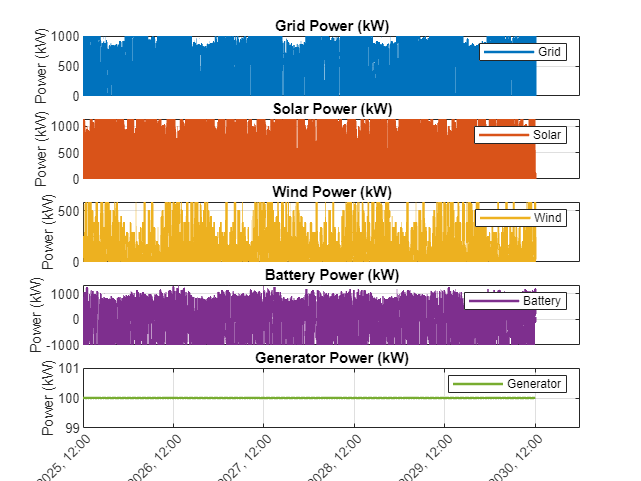

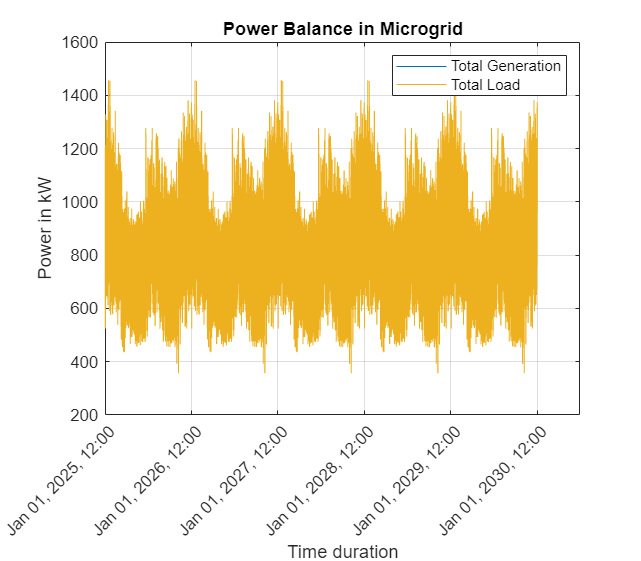

plotOptimalValues(Solution = solution,NormalizedPower = normalizedPower,Years = years);

#### Energy Accounting 

This table shows the energy produced and consumed by different components in the microgrid.

energyVal = getValues.energy(Solution = solution, NormalizedPower = normalizedPower);
energyComponent = {'Grid','Solar','Wind','Generator','Battery Charging','Battery Discharging','Load'};
energyData = [energyVal.grid;energyVal.solar;energyVal.wind;energyVal.generator;energyVal.batteryCharging;energyVal.batteryDisharging;energyVal.load];
energyTable = table(energyComponent', energyData/1000, 'VariableNames', {'Energy Component', 'Value (MWh)'});
disp(energyTable);

       Energy Component        Value (MWh)
    _______________________    ___________

    {'Grid'               }       20738   
    {'Solar'              }      5863.6   
    {'Wind'               }        3831   
    {'Generator'          }        4380   
    {'Battery Charging'   }      5461.6   
    {'Battery Discharging'}      5465.6   
    {'Load'               }       34812   



#### Calculate Micrgrid Costs

These tables shows the capital, operating, and maintanence cost, and fuel cost of different assets in the microgrid. Operating expenses (OPEX) and fuel Cost are calculated yearly.

[capex,opex,fuelCost,costTable] = getValues.costComponents(componentParam,solution,npv,generator.type);
capexTable = costTable(:, {'CAPEX (USD)'});
opexTable = costTable(:, {'OPEX (USD)'});
fuelCostTable = costTable(:, {'FuelCost (USD)'});
disp(capexTable);

                 CAPEX (USD)
                 ___________

    Grid                  0 
    Solar        1.9474e+06 
    Wind         1.5927e+06 
    Battery      8.8042e+05 
    Generator       3.5e+05 
    Total        4.7705e+06 



disp(opexTable);

                                            OPEX (USD)                            
                 _________________________________________________________________

    Grid         8.291e+05     7.901e+05    7.5255e+05    7.1669e+05    6.8254e+05
    Solar            48684         46366         44158         42055         40052
    Wind             17065         16252         15478         14741         14039
    Battery          20543         19565         18633         17746         16901
    Generator         7500        7142.9        6802.7        6478.8        6170.3
    Total        9.229e+05    8.7942e+05    8.3762e+05    7.9771e+05     7.597e+05



disp(fuelCostTable);

                                           FuelCost (USD)                          
                 __________________________________________________________________

    Grid                  0             0             0             0             0
    Solar                 0             0             0             0             0
    Wind                  0             0             0             0             0
    Battery               0             0             0             0             0
    Generator    2.8921e+05    2.7544e+05    2.6232e+05    2.4983e+05    2.3793e+05
    Total        2.8921e+05    2.7544e+05    2.6232e+05    2.4983e+05    2.3793e+05



This chart shows the overall costs associated with the grid and energy sources in the microgrid over the analysis period.

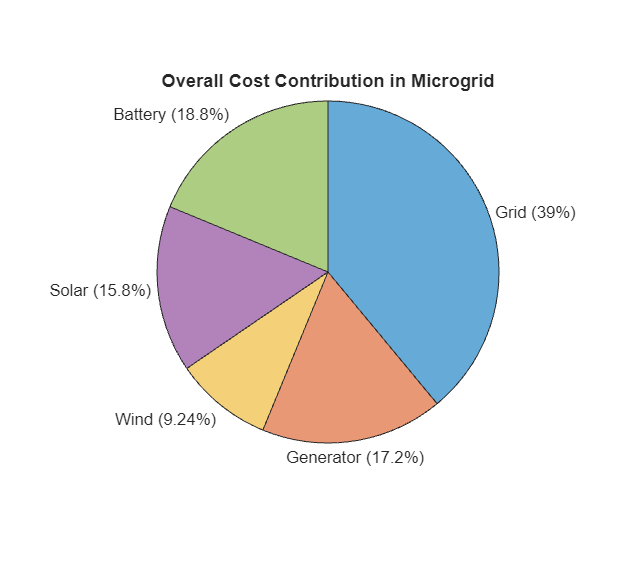

plotCostContribution(cost,solution);

#### **Calculate Capacity Factor**

The capacity factor is an important metric in the assessment of different energy sources, particularly for power generation technologies such as wind farms, solar plants, and microgrids. The capacity factor is the ratio of the actual output of an energy source over a period of time to its potential output if continuously operating at the rated capacity over the same period:


$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{CF}=\frac{\textrm{Actual}\;\textrm{output}}{\textrm{Maximum}\;\textrm{Possible}\;\textrm{output}}$$


This table shows the overall capacity factors for different assets in this example:

assets = {'Solar';'Wind';'Generator'};
capacityFactor = getValues.capacityFactor(solution,normalizedPower,npv);
capacityFactorTable = table(assets, [capacityFactor.solar; capacityFactor.wind; capacityFactor.generator], 'VariableNames', {'Asset', 'Capacity Factor (%)'});
disp(capacityFactorTable)

        Asset        Capacity Factor (%)
    _____________    ___________________

    {'Solar'    }          11.767       
    {'Wind'     }          14.902       
    {'Generator'}             100       



This plot shows the monthly capacity factor for different assets:

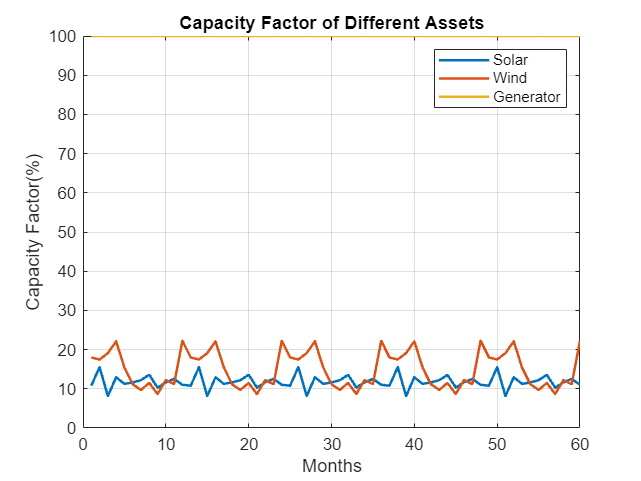

plotCapacityFactor(capacityFactor);

#### **Calculate Levelized Cost of Energy**

The levelized cost of energy (LCOE) is an important metric in energy economics to evaluate the cost-effectiveness of different energy sources. The LCOE represents the per-unit cost (typically per kWh or MWh) of installing and operating an energy source over its lifetime. This example calculates the LCOE using this equation:

LCOE = (CAPEX+ NPV of OPEX) / (NPV of Energy generated)

The LCOE allows for comparisons across various technologies and projects. This plot shows the LCOE for the different energy sources in this example.

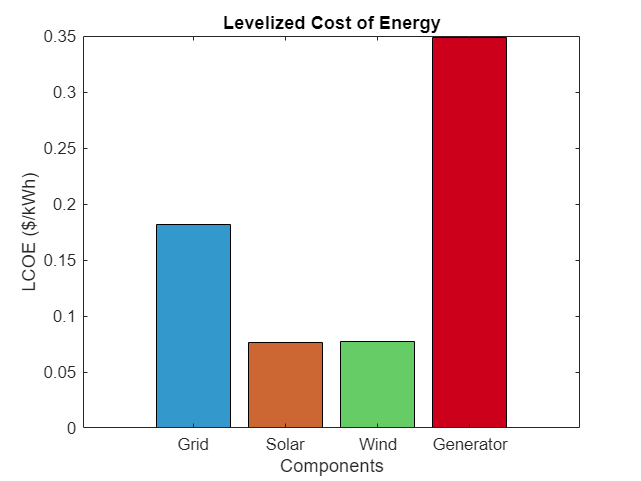

lcoe = getValues.LCOE(Solution = solution,Param = componentParam,Cost = cost,NPV = npv,...
    NormalizedPower = normalizedPower,Components = components);
plotLCOE(lcoe);

## **Run Simulation **

The simulation is run for a period of one year and runs in a phasor-mode. These plots show the simulation results for each of the simulation scenarios:

- Power output from different assets

- Load power

- Comparison between optimization-based energy management system (EMS) and rule-based EMS

### Simulation of Case 1 —  Downtime of Solar PV Plant

Initialize the parameters for case 1 and run the model.

caseNum = 1; %#ok<*NASGU>
TechnoEconomicAnalysisInput;
optimizationMode = 1;
solarPV.downTime = 500;
solarPV.downTimeDuration = 144;
plotTime = solarPV.downTime-10:1:solarPV.downTime+1.5*solarPV.downTimeDuration;
simOutOpt = sim('TechnoEconomicMicrogrid','SrcWorkspace','current');
optimizationMode = 0;
simOutRule = sim('TechnoEconomicMicrogrid','SrcWorkspace','current');

This plot shows the power output of different sources in the microgrid before, during, and after the loss of the solar PV plant.

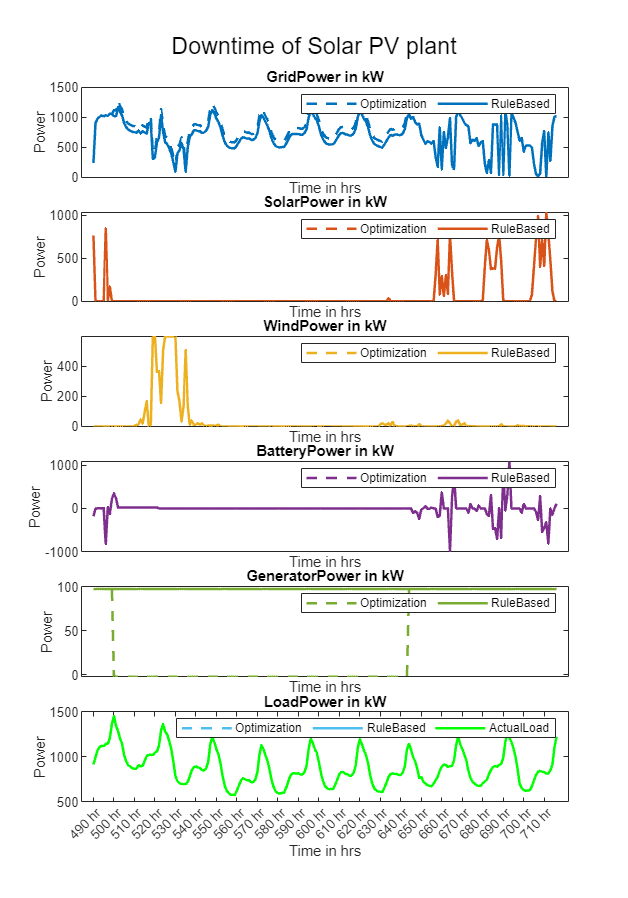

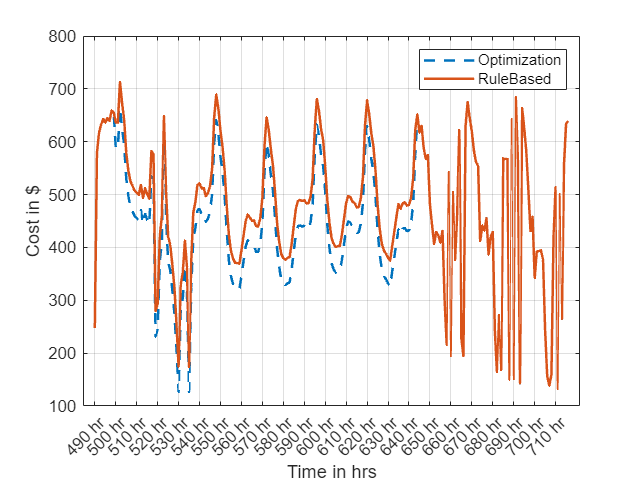

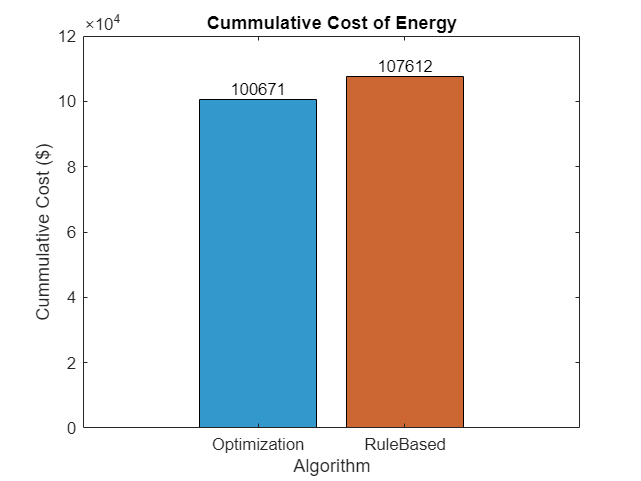

titleName = 'Downtime of Solar PV plant';
plotLength = 1000;
plotCompareAlgorithms(simOutOpt,simOutRule,components,plotTime,titleName,generatorSet,mainGrid,plotLength);

### Simulation of Case 2 —  Downtime of Wind Farm

Initialize the parameters for case 2 and run the model.

caseNum = 2;
TechnoEconomicAnalysisInput;
optimizationMode = 1;
windFarm.downTime = 1000;
windFarm.downTimeDuration = 144;
plotTime = windFarm.downTime-10:1:windFarm.downTime+1.5*windFarm.downTimeDuration;
simOutOpt = sim('TechnoEconomicMicrogrid','SrcWorkspace','current');
optimizationMode = 0;
simOutRule = sim('TechnoEconomicMicrogrid','SrcWorkspace','current');
component = {'Battery','Solar','Wind','Generator','Grid','Load'};

This plot shows the power output of different sources in the microgrid before, during, and after the loss of the wind farm

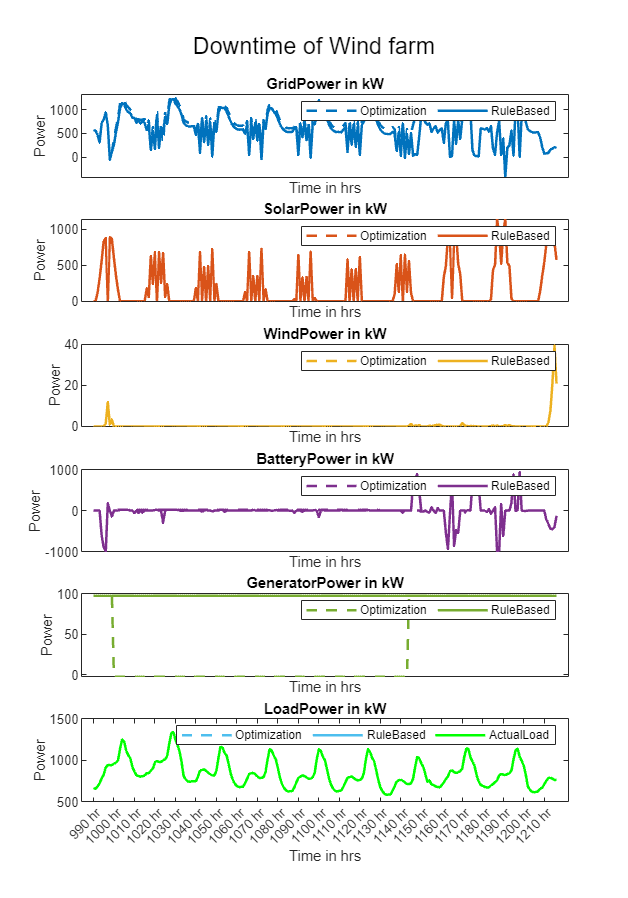

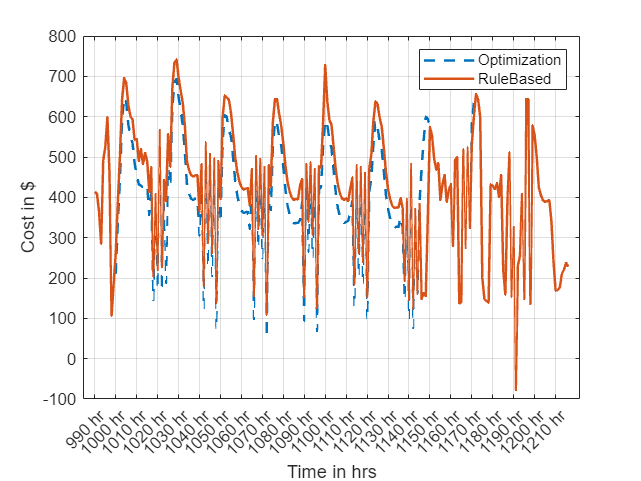

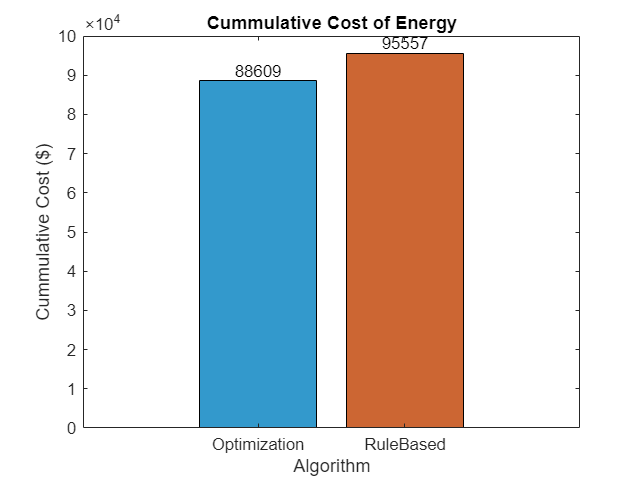

titleName = 'Downtime of Wind farm';
plotCompareAlgorithms(simOutOpt,simOutRule,components,plotTime,titleName,generatorSet,mainGrid,plotLength);

## Run Sensitivity analysis

You can configure the inputs to sensitivity analysis in the [SensitivityAnalysis.mlx](matlab:open('./SensitivityAnalysis.mlx')) file. This example runs the sensitivity analysis on the grid price. The grid price is chosen as a sensitive variable. These plots show the variation of ratings of different assets with respect to the grid price.

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.


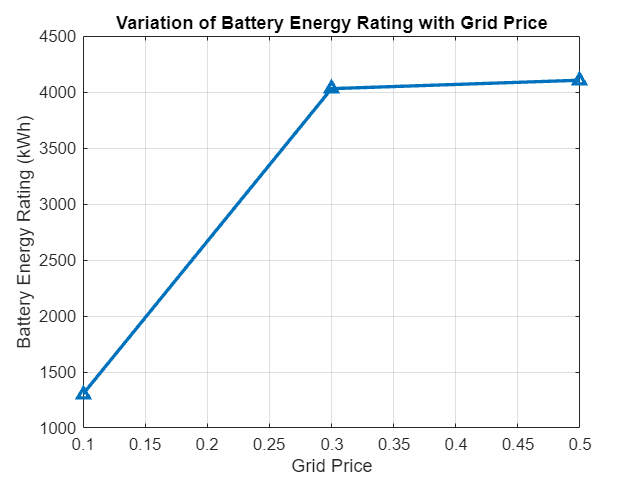

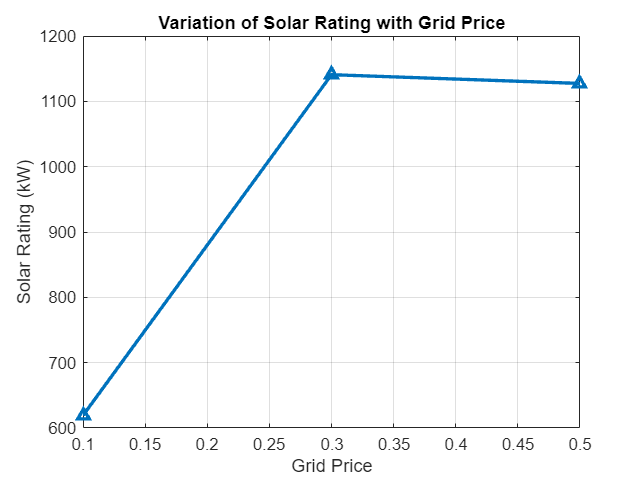

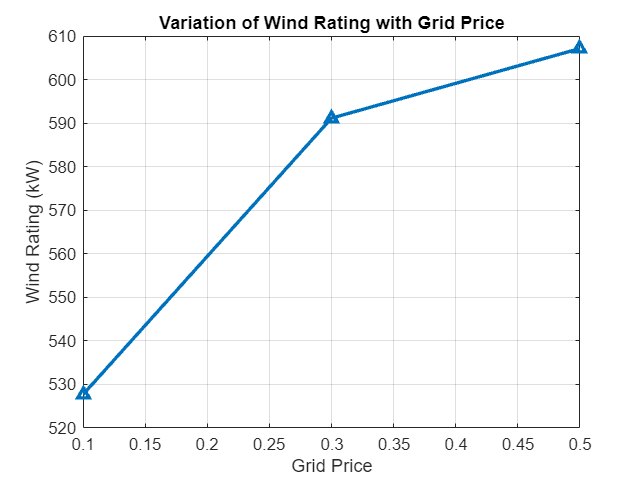

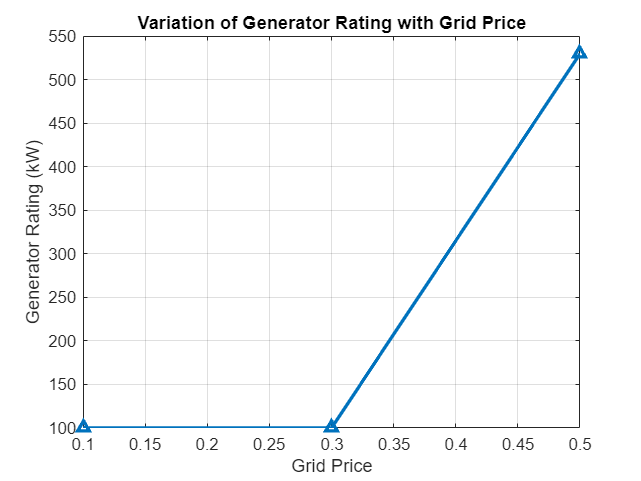

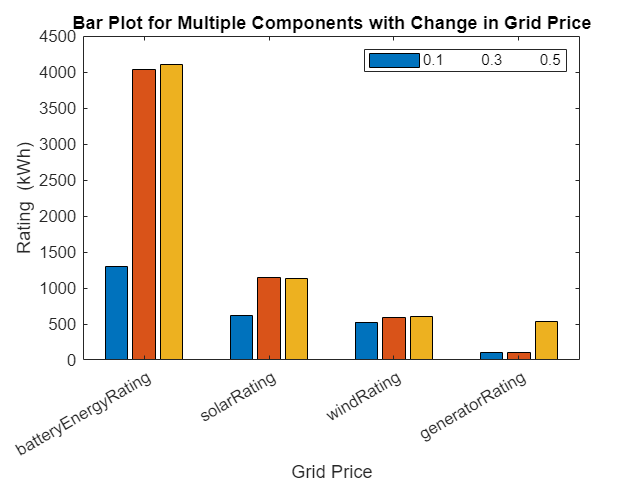

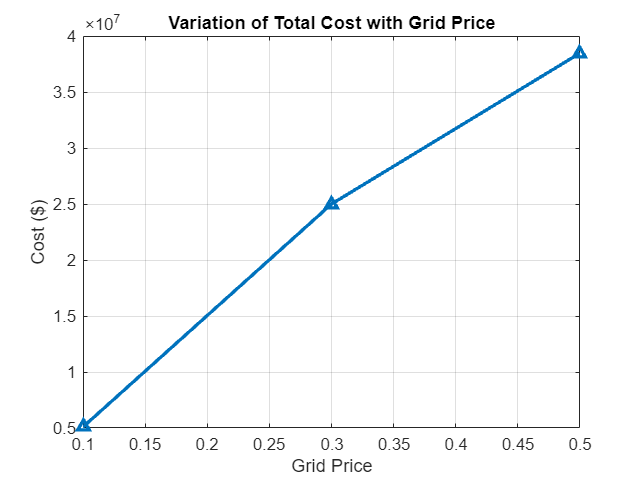

SensitivityAnalysis;

### References

- Øyvin Skarstein, Kjetil Uhlen, "Design Considerations with Respect to Long-Term Diesel Saving in Wind/Diesel Plants," in Wind Engineering, Vol. 13, No. 2 (1989), pp. 72-87

- [https://rtpowersystems.com/cost-of-running-a-generator-on-natural-gas/](https://rtpowersystems.com/cost-of-running-a-generator-on-natural-gas/)

- "McCormick Envelopes.", Cornell University, [https://optimization.cbe.cornell.edu/index.php?title=McCormick_envelopes#References.](https://optimization.cbe.cornell.edu/index.php?title=McCormick_envelopes#References.)

- IEEE 2030.9-2019-IEEE Recommended Practice for the Planning and Design of the Microgrid.

Copyright 2024 The MathWorks, Inc.